clear


%パラメータ
L = 0.045; %端子間インダクタンス[mH]　
R = 2.9; %端子間抵抗[ohm]
Kt = 3.52e-3; %トルク定数[Nm/A]
J = 0.151e-7; %イナーシャ[kgm^2]
d = 0.00001; % 粘性抵抗
Ke = 1 / (2 * pi * 2710 / 60); %逆起電定数 [V/(rad/s)]

r = 0.012; %タイヤの半径 [m]
m = 0.150; %ロボットの重量[kg]
g = 1; %減速比


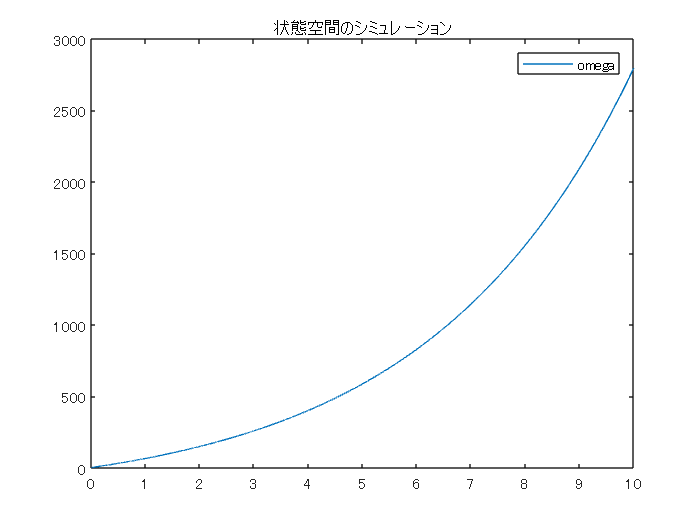

%状態空間表現
A = [d/(m*r^2 + J),Kt/(m*r^2 + J); -Ke/L, -R/L];
B = [0; 1/L];
C = [1, 0];
D = 0;
sys_state = ss(A,B,C,D);

%状態空間でシミュレーション
dt = 0.001;
t = 0 : dt : 10;
N = length(t);
i = 0;
x = [0; 0];
u = 1;
x1 = zeros(1, N);
x2 = zeros(1, N);
for n = t
    i = i + 1;
    dx = A * x + B * u;
    x = x + dx * dt;
    
    x1(i) = [x(1)];
    x2(i) = [x(2)];
end

plot(t, x1);
legend('omega')
title('状態空間のシミュレーション')

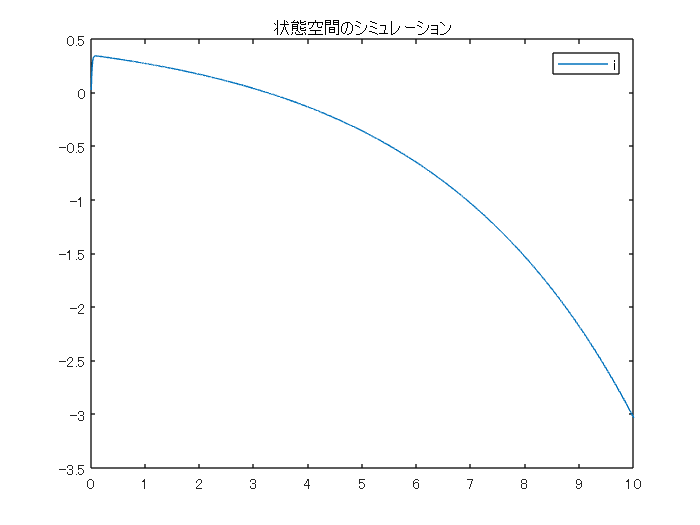


plot(t, x2);
legend('i')
title('状態空間のシミュレーション')


%サーボ系構築

Ab = [A, zeros(2, 1);
      -C, 0];
Bb = [B; 0];

% 可制御　可観測
Uc = [Bb, Ab*Bb, Ab^2*Bb];
if det(Uc) ~= 0
    disp('可制御である')
end

可制御である


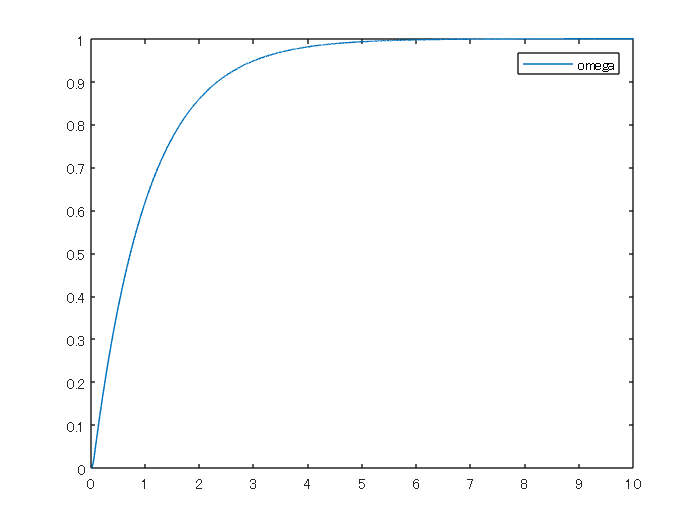

C = [1, 0, 0];
Uo = [C; C*Ab; C*Ab^2];

if det(Uo) ~= 0
    disp('可観測である')
end
%ゲインを求める
Q = [1, 0, 0;
     0, 1, 0;
     0, 0, 1];
R = 1;
gain = lqr(Ab, Bb, Q, R);
f = gain(1:2);
k = -gain(3);

% 状態フィードバックのシミュレーション
x0 = [0; 0]; % 初期値
u = 0; % 入力の初期値
xb0 = x0;
z = 0; % 偏差の積分
v = [0; 0]; % 外乱
r = 1; % 目標値

u = 0; % 入力の初期値
xb = xb0;

s_x1 = [];
s_x2 = [];
s_z = [];
s_u = [];
for n = t
    dxb = Ab * [xb; z] + Bb * u + [v; r];
    xb = xb + dxb(1:2, 1) * dt;
    z = z + dxb(3) * dt;
    u = -f*xb + k*z;
    
    s_x1 = [s_x1 xb(1)];
    s_x2 = [s_x2 xb(2)];
    s_z = [s_z z];
    s_u = [s_u u];

end

plot(t, s_x1);
legend('omega')

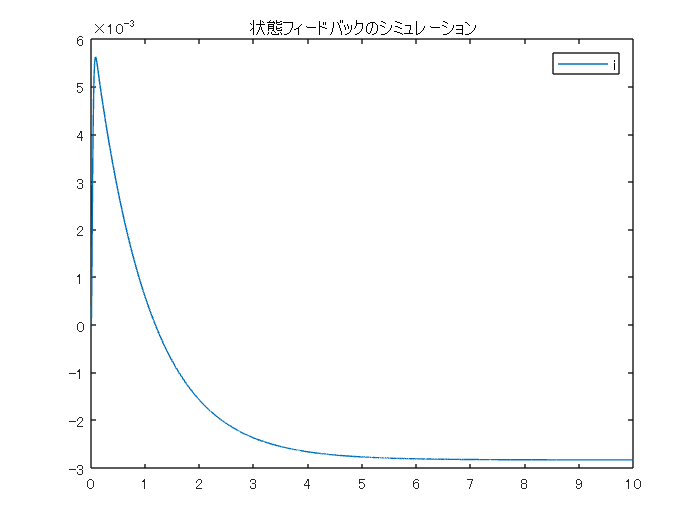

plot(t, s_x2);
legend('i')
title('状態フィードバックのシミュレーション')